clear all; close all; clc;

%% Load the synthesis matrix and parameters
load('synthesis_matrix.mat');

size(synthesis_matrix)

ans =     64    52


N_filter

N_filter = 16

filter_chunk

filter_chunk = 4

mat_its

mat_its = 13

normal_filter

normal_filter =          0   -0.0034    0.0152    0.0388   -0.0798   -0.1517    0.3048    1.0000    1.0000    0.3048   -0.1517   -0.0798    0.0388    0.0152   -0.0034         0



test_signal = sin(2*pi*(0:input_length-1)*0.1)

test_signal =          0    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878   -0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878   -0.0000   -0.5878   -0.9511   -0.9511   -0.5878




%% Forward Process
% Create input signal vector
input_signal = test_signal;

% Parameters + Pre-allocation
num_full_blocks = floor(length(input_signal) / filter_chunk);               
mat_its_test = floor((length(input_signal) - N_filter) / filter_chunk) + 1;      
stored_matrix = cell(mat_its_test, 1);                                           
stored_fft_blocks = cell(mat_its_test, 1);                                       
output_cols = mat_its_test * filter_chunk + N_filter - 4;                        
output_mat = zeros(mat_its_test * filter_chunk, output_cols);                    
padded_length = num_full_blocks * filter_chunk + N_filter - filter_chunk;  
matrix = zeros(filter_chunk, N_filter);
fft_matrix = zeros(mat_its_test*filter_chunk, mat_its_test*filter_chunk);

% Pad input signal with zeros to handle edge effects
input_padded = [input_signal, zeros(1, max(0, padded_length - length(input_signal)))];

fprintf('\nForward process:\n');


Forward process:


fprintf('  mat_its for test: %d\n', mat_its_test);

  mat_its for test: 13


fprintf('  Padded length: %d\n', length(input_padded));

  Padded length: 76



% Main analysis loop - process input signal in blocks
for j = 1:mat_its_test
    startpoint = (j-1) * filter_chunk + 1;
    blockend = startpoint + N_filter - 1;
    values = startpoint:blockend;
    
    % Apply filter to input segment
    Y = input_signal(values) .* normal_filter;    
    
    % Fill matrix with filtered values in polyphase arrangement
    for i = 1:N_filter
        matrix(mod(i-1, filter_chunk) + 1, i) = Y(i);
    end 
    stored_matrix{j} = matrix;

    % Place matrix block into overall output matrix
    row_start = (j-1) * filter_chunk + 1;
    row_end = j * filter_chunk;
    col_start = (j-1) * filter_chunk + 1;
    col_end = col_start + N_filter - 1;   
    if col_end <= output_cols
        output_mat(row_start:row_end, col_start:col_end) = stored_matrix{j};
    end
end

K = filter_chunk;
M = K;  % Decimation/interpolation factor
Xk_matrix = zeros(K, mat_its*K);

% Apply matrix-based 2D DFT to each stored matrix block
for i = 1:mat_its_test
    % Get branch outputs (sum across taps for each branch)
    branch_outputs = sum(stored_matrix{i}, 2);  % K × 1 vector
    
    % Apply DFT using matrix multiplication
    Xk_m = W .* branch_outputs;  
    
    % Store directly in Xk_matrix
    Xk_matrix(:, (i-1) * K + 1:i*K) = Xk_m;
    
    % For visualization, create block diagonal FFT matrix structure
    currentblock = Xk_m;  % Put frequency coefficients on diagonal
    stored_fft_blocks{i} = currentblock;

    % Place FFT block into overall FFT matrix
    blockstart = (i-1)*filter_chunk + 1;
    blockend = i*filter_chunk;
    fft_matrix(blockstart:blockend, blockstart:blockend) = currentblock;
end

## Original Synthesis

% Initialize output signal
output_length_synth = length(input_signal) + N_filter;
reconstructed_original = zeros(1, output_length_synth);

% Synthesis filter
synthesis_filter = normal_filter;

% Process each time block m
for m = 1:mat_its
    blockstart = (m-1)*K + 1;
    blockend = m*K;
    
    % Get the m-th diagonal block from fft_matrix
    freq_block = fft_matrix(blockstart:blockend, blockstart:blockend);
    
    % Directly perform IFFT on each column of freq_block
    % Resulting time_samples will be K x K
    time_samples_block = freq_block.*W_inv;  % IFFT along columns by default
    
    % Upsample and overlap-add each column
    for col = 1:K
        time_samples = diag(time_samples_block);  % diagonal of time samples
        
        %Zero-pad length of signal (upsample by M)
        upsampled_length = K * M;
        upsampled = zeros(1, upsampled_length);
        upsampled(1:M:end) = time_samples;
        
        % Conv. with synthesis filter (reverse-time input filter)
        filtered = conv(upsampled, synthesis_filter);
        
        %Time shifting and add individual sums together
        time_shift = (m-1) * M;  % zero-based
        output_start = time_shift + 1;
        output_end = min(output_start + length(filtered) - 1, output_length);
        valid_length = output_end - output_start + 1;
        
        % Overlap-add (implements the sum over m)
        reconstructed_original(output_start:output_end) = ...
            reconstructed_original(output_start:output_end) + real(filtered(1:valid_length));
    end
end

input_rms = rms(input_signal);
reconstructed_rms = rms(reconstructed_original);

gain_correction = input_rms / reconstructed_rms;
reconstructed_original = reconstructed_original * gain_correction;

RealPart = reconstructed_original

RealPart =          0    0.0029   -0.0133   -0.0339    0.0696    0.1298   -0.2545   -0.8434   -0.9336   -0.3800    0.3578    0.8139    0.7605    0.2871   -0.2608   -0.5334   -0.2914    0.0714   -0.3046   -1.1851   -1.4229   -0.6324    0.6585    1.6349    1.6349    0.6554   -0.6185   -1.3875   -1.2578   -0.4420    0.3453    0.6101    0.4003    0.0597    0.0597    0.4003    0.6101    0.3453   -0.4420   -1.2578   -1.3875   -0.6185    0.6554    1.6349    1.6349    0.6554   -0.6185   -1.3875   -1.2578   -0.4420


input_signal

input_signal =          0    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878   -0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878   -0.0000   -0.5878   -0.9511   -0.9511   -0.5878



% Trim to input signal length
reconstructed_original = reconstructed_original(1:length(input_signal));


## Matrix-based reconstruction

% Flatten Xk_matrix
for i = 1:mat_its
    Xk_flat((i-1) * K + 1:i*K,:) = diag(Xk_matrix(:,(i-1) * K + 1:i*K));  % Row vector
end

fprintf('Xk_flat size: 1 × %d\n', length(Xk_flat));

Xk_flat size: 1 × 52


fprintf('Synthesis matrix size: %d × %d\n', size(synthesis_matrix));

Synthesis matrix size: 64 × 52



% Apply synthesis matrix
reconstructed_matrix = Xk_flat' * synthesis_matrix_transpose;

matrix_rms = rms(reconstructed_matrix);
reconstructed_matrix = reconstructed_matrix * input_rms / matrix_rms

reconstructed_matrix =    0.0000 + 0.0000i   0.0017 + 0.0000i  -0.0077 - 0.0000i  -0.0197 - 0.0000i   0.0405 + 0.0000i   0.0757 + 0.0000i  -0.1487 - 0.0000i  -0.4924 - 0.0000i  -0.5410 - 0.0000i  -0.2163 + 0.0000i   0.1982 - 0.0000i   0.4406 - 0.0000i   0.4102 + 0.0000i   0.1592 + 0.0000i  -0.1544 + 0.0000i  -0.3283 - 0.0000i  -0.1456 + 0.0000i   0.0960 - 0.0000i  -0.2852 + 0.0000i  -1.0529 - 0.0000i  -1.2609 + 0.0000i  -0.5722 + 0.0000i   0.6107 - 0.0000i   1.5426 - 0.0000i   1.5626 + 0.0000i   0.6361 - 0.0000i  -0.6114 - 0.0000i  -1.3969 + 0.0000i  -1.2900 - 0.0000i  -0.4658 + 0.0000i   0.3804 + 0.0000i   0.7176 - 0.0000i   0.5246 - 0.0000i   0.1176 + 0.0000i  -0.0041 - 0.0000i   0.2357 + 0.0000i   0.4412 - 0.0000i   0.2755 + 0.0000i  -0.3737 + 0.0000i  -1.0991 + 0.0000i  -1.2384 + 0.0000i  -0.5634 + 0.0000i   0.6088 + 0.0000i   1.5426 + 0.0000i   1.5626 - 0.0000i   0.6361 - 0.0000i  -0.6114 - 0.0000i  -1.3969 + 0.0000i  -1.2900 - 0.0000i  -0.4658 - 0.0000i



% Calculate errors
reconstruction_error = reconstructed_matrix - reconstructed_original;
mse = mean(reconstruction_error.^2);
max_error = max(abs(reconstruction_error));
rmse = sqrt(mse);

fprintf('Mean Squared Error: %.6e\n', mse);

Mean Squared Error: 2.456820e-02


fprintf('Root Mean Squared Error: %.6e\n', rmse);

Root Mean Squared Error: 1.567425e-01


fprintf('Maximum Error: %.6e\n', max_error);

Maximum Error: 4.074024e-01



% Calculate correlation
correlation = corrcoef(reconstructed_original, reconstructed_matrix);
fprintf('Correlation: %.6f\n', correlation(1,2));

Correlation: 0.984358



% Calculate SNR
signal_power = mean(reconstructed_original.^2);
noise_power = mean(reconstruction_error.^2);
if noise_power > 0
    snr_db = 10*log10(signal_power / noise_power);
    fprintf('SNR: %.2f dB\n', snr_db);
end

SNR: 14.08 dB


## Visualization

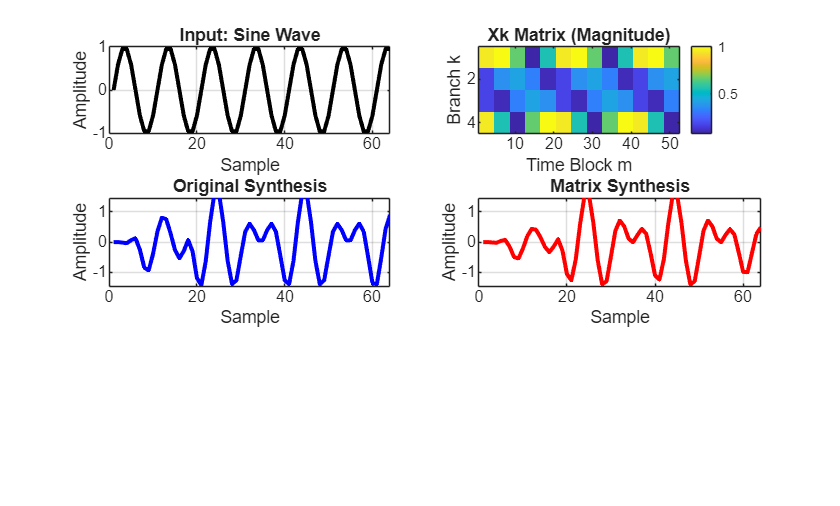

figure('Name', 'Synthesis Matrix Test: Sine Wave', 'NumberTitle', 'off');

% Input signal
subplot(3,2,1);
plot(1:length(test_signal), test_signal, 'k-', 'LineWidth', 2);
title('Input: Sine Wave');
xlabel('Sample');
ylabel('Amplitude');
grid on;

% Frequency domain magnitude
subplot(3,2,2);
imagesc(abs(Xk_matrix));
colormap('parula');
colorbar;
title('Xk Matrix (Magnitude)');
xlabel('Time Block m');
ylabel('Branch k');

% Original synthesis reconstruction
subplot(3,2,3);
plot(1:length(reconstructed_original), reconstructed_original, 'b-', 'LineWidth', 2);
title('Original Synthesis');
xlabel('Sample');
ylabel('Amplitude');
grid on;
ylim([min(test_signal)-0.5, max(test_signal)+0.5]);

% Matrix synthesis reconstruction
subplot(3,2,4);
plot(1:length(reconstructed_matrix), real(reconstructed_matrix), 'r-', 'LineWidth', 2);
title('Matrix Synthesis');
xlabel('Sample');
ylabel('Amplitude');
grid on;
ylim([min(test_signal)-0.5, max(test_signal)+0.5]);

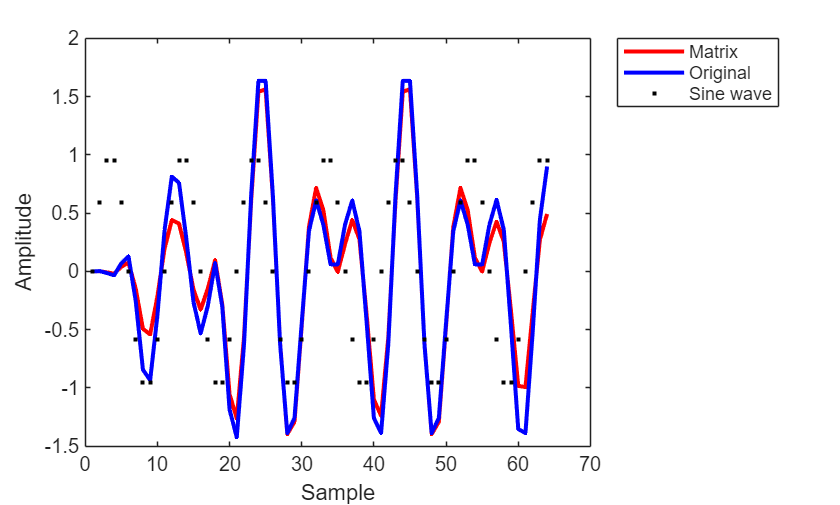


figure;
plot(1:length(reconstructed_matrix), real(reconstructed_matrix), 'r-', 'LineWidth', 2);
hold on
plot(1:length(reconstructed_original), reconstructed_original, 'b-', 'LineWidth', 2);
plot(1:length(test_signal), test_signal, 'k.', 'LineWidth', 2);
hold off
legend('Matrix', 'Original', 'Sine wave', 'location', 'northeastoutside')
xlabel('Sample')
ylabel('Amplitude')

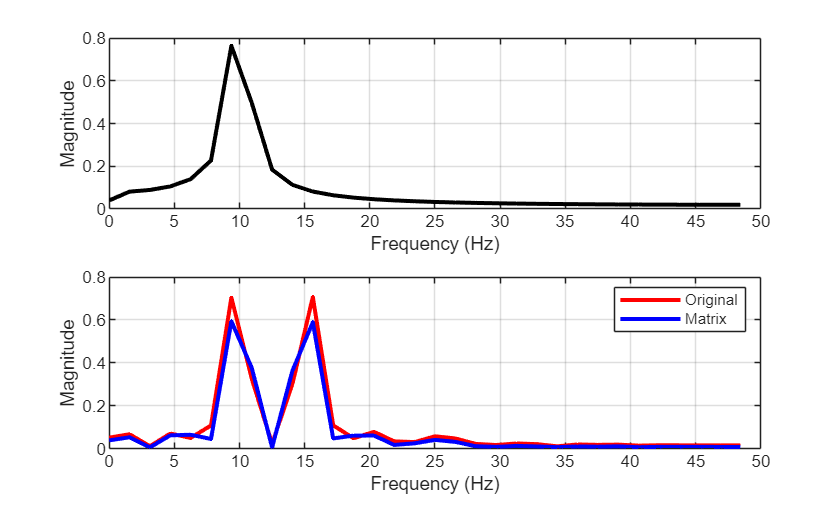


% Frequency response - input signal
fs = 100;
N = length(input_signal);
X = fft(input_signal);
X_mag = abs(X)/N;
X_mag(2:end-1) = 2*X_mag(2:end-1);
freq = (0:N-1)*fs/N;

% Frequency response - original and reconstructed signal
N = length(reconstructed_matrix);
R = fft(reconstructed_matrix);
R_mag = abs(R)/N;
R_mag(2:end-1) = 2*R_mag(2:end-1);

N = length(reconstructed_original);
M = fft(reconstructed_original);
M_mag = abs(M)/N;
M_mag(2:end-1) = 2*M_mag(2:end-1);


figure;
subplot(2,1,1)
plot(freq(1:N/2), X_mag(1:N/2), ['k-'], 'LineWidth', 2);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

subplot(2,1,2)
plot(freq(1:N/2), M_mag(1:N/2),'r-', 'LineWidth', 2);
hold on
plot(freq(1:N/2), R_mag(1:N/2), 'b-', 'LineWidth', 2);
legend('Original', 'Matrix', 'Location', 'northeast')
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

Identity = synthesis_matrix * fft_matrix

Identity =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0009 + 0.0000i   0.0007 + 0.0000i